#### Define Mission Start and Parameters

inMissionProgress = false;

%This can be updated to change the number of UAVs
numDrones = 2;

# Begin Search Loop

#### Load Map

% Set RNG seed for repeatable result
rng(1,"twister");

mapData = load("uavMapCityBlock.mat","omap");
omap = mapData.omap;
% Consider unknown spaces to be unoccupied
omap.FreeThreshold = omap.OccupiedThreshold;

#### Define the State Space Object

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[-20 220; -20 220; 10 100; -pi pi]);

#### Define the State Validator Object

sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.1;

#### Define Start and Goal Poses

helperPlanner = plannerRRT(ss, sv);

%Start Poses: Populated artifically when the mission is starting
if ~inMissionProgress
    droneStartPoses = zeros(numDrones, 4);
    for i = 1:numDrones
        droneStartPoses(i, :) = findValidPose(helperPlanner);
    end
end

pose =    80.0853  152.8779   10.0103   -1.2420


pose =     2.1613   24.7025   41.1005   -0.6486


pose =    80.6067  144.4527   28.4007    2.3758


pose =   140.9122   80.1532   60.2821   -2.2595


%Each row corresponds to one drone states (n x 4)
droneStartPoses

droneStartPoses =     2.1613   24.7025   41.1005   -0.6486
  140.9122   80.1532   60.2821   -2.2595


%Goal Poses: Always populated artificially
droneGoalPoses = zeros(numDrones, 4);
for i = 1:numDrones
    droneGoalPoses(i, :) = findValidPose(helperPlanner);
end

pose =   172.1787  212.3828   38.2082    1.2084


pose =   194.7056    0.4106   13.5149   -2.0745


droneGoalPoses;

%Hardcoded droneGoalPoses, uncomment if desired
% droneGoalPoses = [
%     150 180 35 pi/2;
%     80 90 40 pi/4;
%     % Add more goal poses as needed
% ]
%droneGoalPoses = droneGoalPoses(2,:)


#### Plot Initial Map

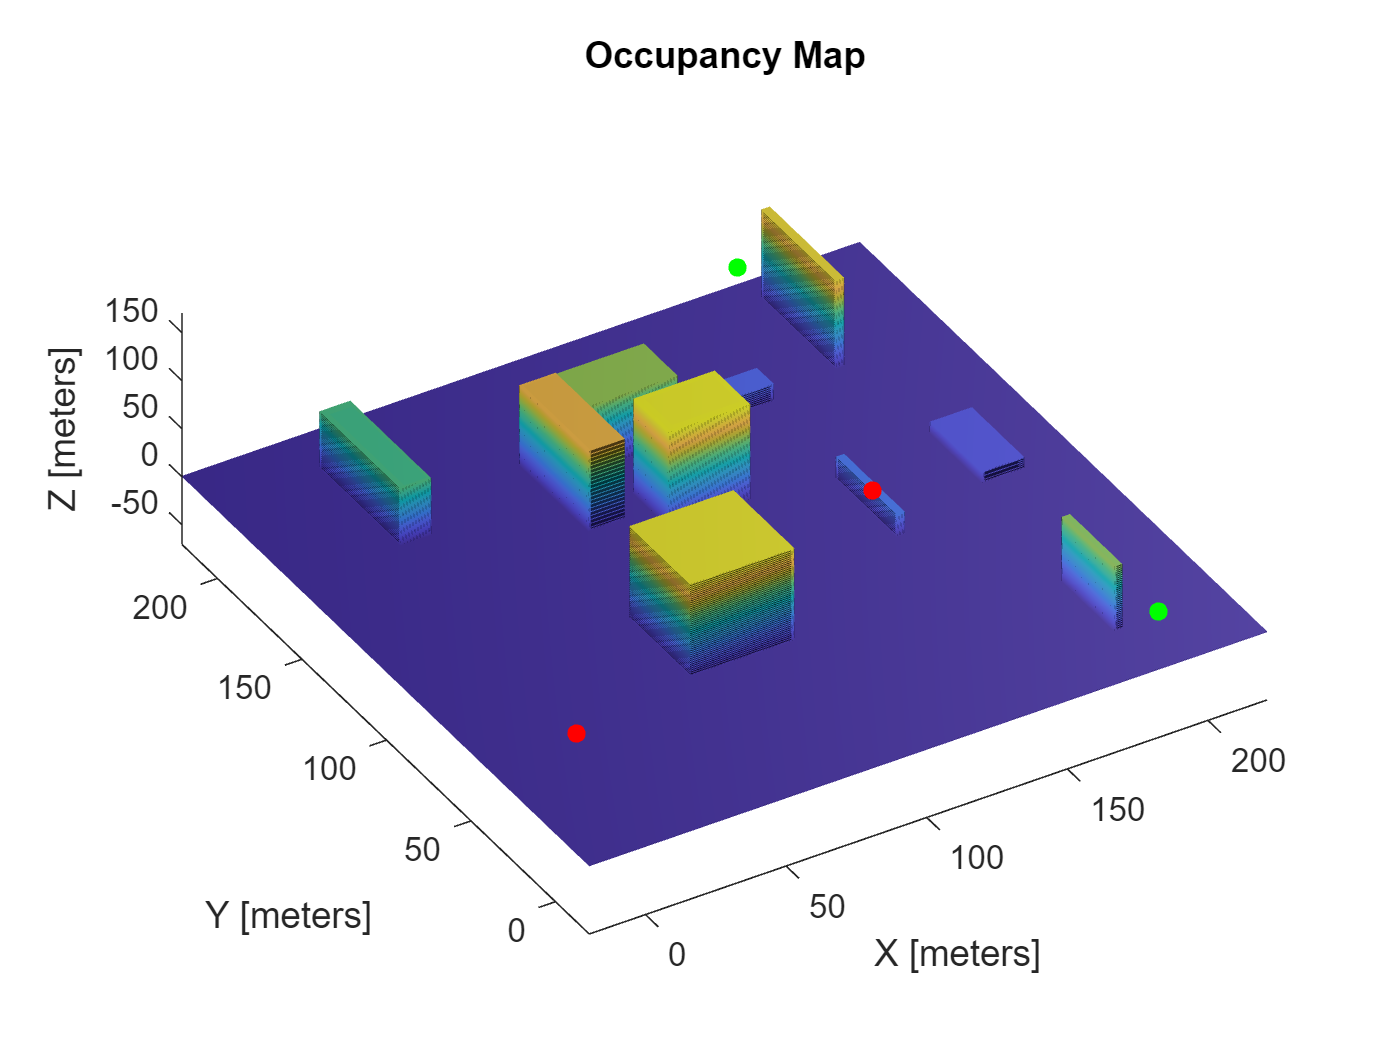

% Plot start and goal poses
figure("Name","StartAndGoal")
hMap = show(omap); 
hold on

% Plot all start poses in red
for i = 1:size(droneStartPoses, 1)
    scatter3(hMap, droneStartPoses(i, 1), droneStartPoses(i, 2), droneStartPoses(i, 3), 30, "red", "filled");
end

% Plot all goal poses in greens
for i = 1:size(droneGoalPoses, 1)
    scatter3(hMap, droneGoalPoses(i, 1), droneGoalPoses(i, 2), droneGoalPoses(i, 3), 30, "green", "filled");
end

hold off
view([-31 63]) % Adjust view angle as needed

#### Create Swarm of Drones

swarm = cell(1, numDrones);

for i = 1:numDrones
    startPose = droneStartPoses(i, :);
    swarm{i} = Drone(startPose, droneGoalPoses, ss, sv);
end

#### Execute MultiGoalRRT for Each Drone

for i = 1:length(swarm)
    swarm{i} = swarm{i}.planPaths();
    swarm{i}.GoalSolns
end

ans = 2×1 cell array
    {1×1 navPath}
    {1×1 navPath}


ans = 2×1 cell array
    {1×1 navPath}
    {1×1 navPath}


#### Plot all Drone Solutions

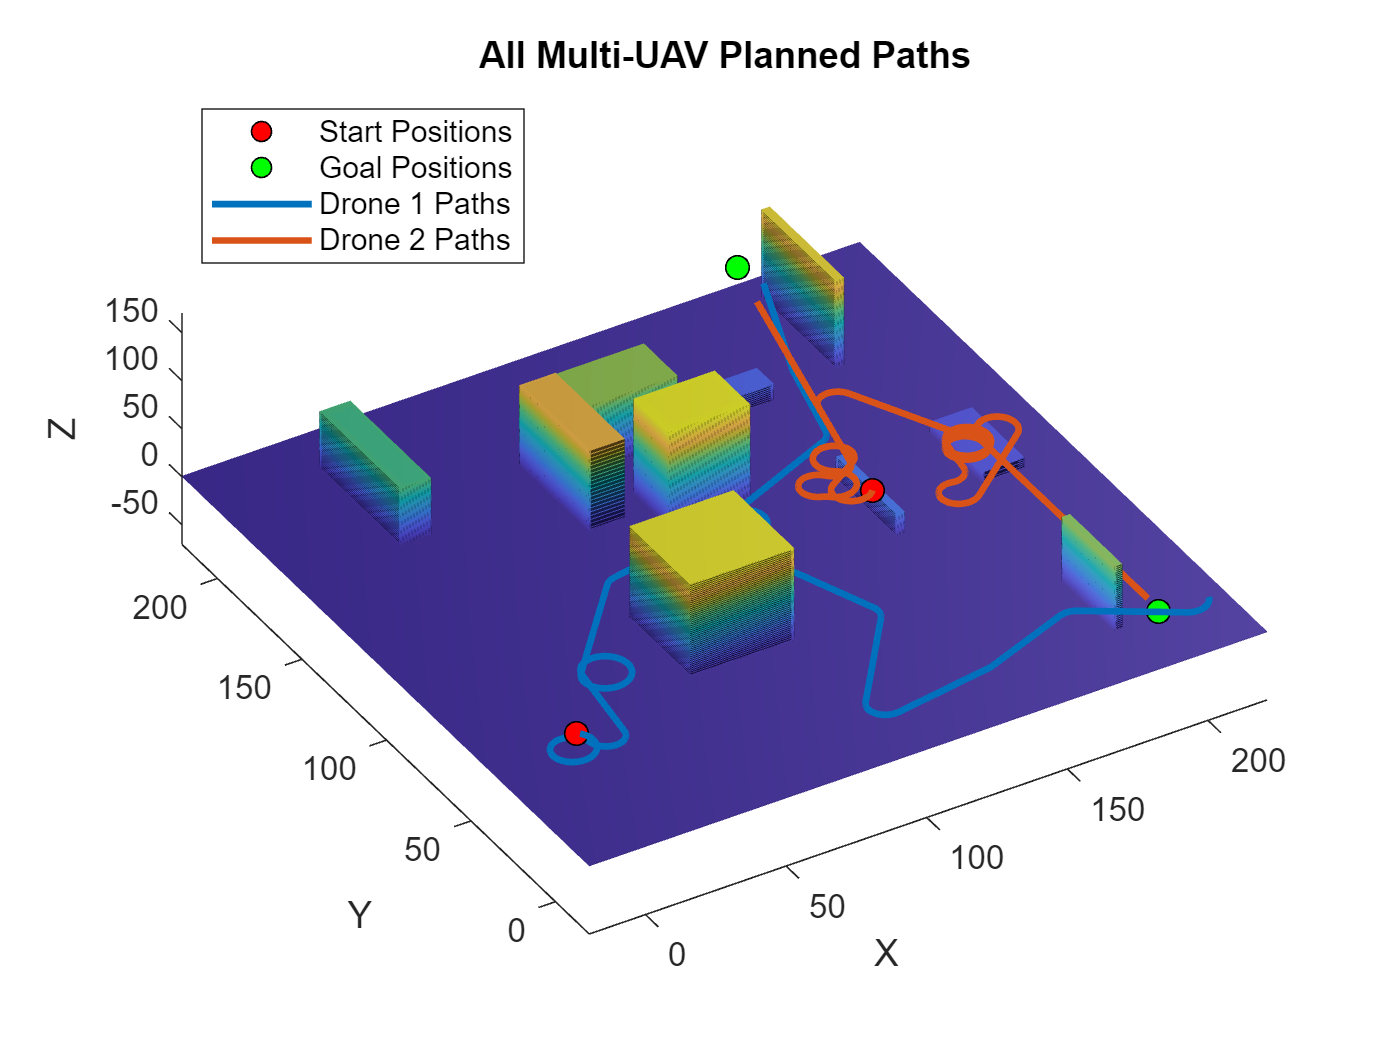

figure("Name", "All Drone Paths")
hMap = show(omap);
hold on

% Define a color map for different drones
colorMap = lines(length(swarm));

% Plot start positions
hStart = scatter3([], [], [], 50, 'r', 'filled', 'MarkerEdgeColor', 'k');

% Plot goal positions
hGoal = scatter3([], [], [], 50, 'g', 'filled', 'MarkerEdgeColor', 'k');

% Initialize an array to store handles for drone paths
hDrones = gobjects(1, length(swarm));

for i = 1:length(swarm)
    drone = swarm{i};
    
    % Plot start position
    scatter3(drone.StartPose(1), drone.StartPose(2), drone.StartPose(3), 50, 'r', 'filled', 'MarkerEdgeColor', 'k')
    
    % Plot goal positions
    scatter3(drone.GoalPoses(:,1), drone.GoalPoses(:,2), drone.GoalPoses(:,3), 50, 'g', 'filled', 'MarkerEdgeColor', 'k')
    
    % Plot paths to all reached goals
    for j = 1:length(drone.GoalSolns)
        if ~isempty(drone.GoalSolns{j})
            path = drone.GoalSolns{j};
            interpolatedPath = copy(path);
            interpolate(interpolatedPath, 1000);
            
            % Plot the interpolated path
            hDrones(i) = plot3(interpolatedPath.States(:,1), ...
                               interpolatedPath.States(:,2), ...
                               interpolatedPath.States(:,3), ...
                               'LineWidth', 2, 'Color', colorMap(i,:));
        end
    end
end

% Create legend
legend_entries = [hStart, hGoal];
legend_labels = {'Start Positions', 'Goal Positions'};

for i = 1:length(swarm)
    if isvalid(hDrones(i))
        legend_entries(end+1) = hDrones(i);
        legend_labels{end+1} = sprintf('Drone %d Paths', i);
    end
end

legend(legend_entries, legend_labels, 'Location', 'best')

hold off
view([-31 63])
title('All Multi-UAV Planned Paths')
xlabel('X')
ylabel('Y')
zlabel('Z')

#### Assign Least Cost Path to Drone

%Display costs
for i = 1:length(swarm)
    drone = swarm{i};
    drone.GoalCosts
end

ans =   386.7192
  521.3214


ans =   224.6194
  529.0450


%Create cost matrix
Costs = cell2mat(arrayfun(@(i) swarm{i}.GoalCosts(:)', 1:length(swarm), 'UniformOutput', false)')

Costs =   386.7192  521.3214
  224.6194  529.0450


Costs(isinf(Costs)) = 1e6  % Replace Inf with a large number

Costs =   386.7192  521.3214
  224.6194  529.0450



%Apply Munkres algorithm
[matchedPairs] = matchpairs(Costs, 1e6) % Solve for minimum cost

matchedPairs =      2     1
     1     2


for i = 1:size(matchedPairs, 1)
    droneIdx = matchedPairs(i, 1);  % Drone index
    goalIdx = matchedPairs(i, 2);  % Goal index

    if Costs(droneIdx, goalIdx) == 1e6
        % Handle unreachable case
        fprintf('Drone %d cannot reach Goal %d. Assigning fallback.\n', droneIdx, goalIdx);
        assignedGoal = find(swarm{droneIdx}.ReachedGoals, 1); % Find reached goal
        if isempty(assignedGoal)
            fprintf('Drone %d has no fallback. Marking as idle.\n', droneIdx);
            swarm{droneIdx}.AssignedGoal = NaN; % Mark as idle
        else
            swarm{droneIdx}.AssignedGoal = assignedGoal;
        end
    else
        % Assign valid goal
        swarm{droneIdx}.AssignedGoal = goalIdx;
        fprintf('Drone %d assigned to Goal %d\n', droneIdx, goalIdx);
    end
end

Drone 2 assigned to Goal 1
Drone 1 assigned to Goal 2


#### Plot Assigned Solutions

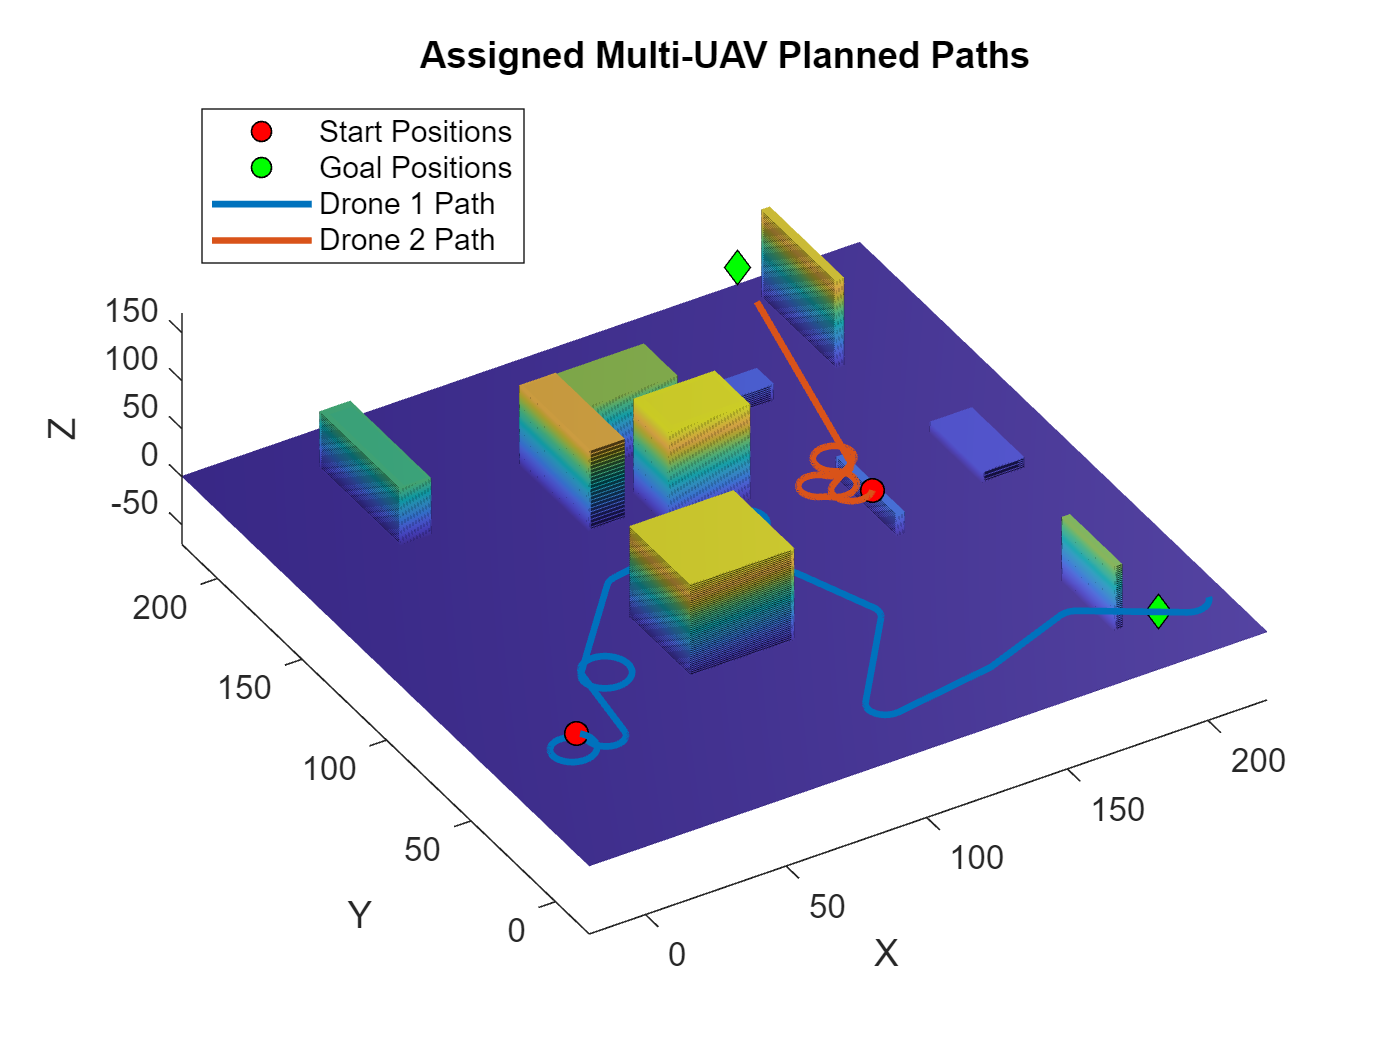

figure("Name", "Assigned Drone Paths")
hMap = show(omap);
hold on

% Define a color map for different drones
colorMap = lines(length(swarm));

% Plot start positions
hStart = scatter3([], [], [], 50, 'r', 'filled', 'MarkerEdgeColor', 'k');

% Plot goal positions
hGoal = scatter3([], [], [], 50, 'g', 'filled', 'MarkerEdgeColor', 'k');

% Initialize an array to store handles for drone paths
hDrones = gobjects(1, length(swarm));

for i = 1:length(swarm)
    drone = swarm{i};
    
    % Plot start position
    scatter3(drone.StartPose(1), drone.StartPose(2), drone.StartPose(3), 50, 'r', 'filled', 'MarkerEdgeColor', 'k')
    
    % Get the assigned goal
    assignedGoal = drone.AssignedGoal;
    
    if ~isnan(assignedGoal) && assignedGoal > 0
        % Plot assigned goal position
        scatter3(drone.GoalPoses(assignedGoal, 1), ...
                 drone.GoalPoses(assignedGoal, 2), ...
                 drone.GoalPoses(assignedGoal, 3), ...
                 50, 'g', 'filled', 'MarkerEdgeColor', 'k', 'Marker', 'diamond');
        
        % Plot the path to the assigned goal if it exists
        if assignedGoal <= length(drone.GoalSolns) && ~isempty(drone.GoalSolns{assignedGoal})
            path = drone.GoalSolns{assignedGoal};
            interpolatedPath = copy(path);
            interpolate(interpolatedPath, 1000);
            
            % Plot the interpolated path
            hDrones(i) = plot3(interpolatedPath.States(:, 1), ...
                               interpolatedPath.States(:, 2), ...
                               interpolatedPath.States(:, 3), ...
                               'LineWidth', 2, 'Color', colorMap(i, :));
        end
    else
        fprintf('Drone %d has no assigned goal.\n', i);
    end
end

% Create legend
legend_entries = [hStart, hGoal];
legend_labels = {'Start Positions', 'Goal Positions'};

for i = 1:length(swarm)
    if isvalid(hDrones(i))
        legend_entries(end+1) = hDrones(i);
        legend_labels{end+1} = sprintf('Drone %d Path', i);
    end
end

legend(legend_entries, legend_labels, 'Location', 'best')

hold off
view([-31 63])
title('Assigned Multi-UAV Planned Paths')
xlabel('X')
ylabel('Y')
zlabel('Z')

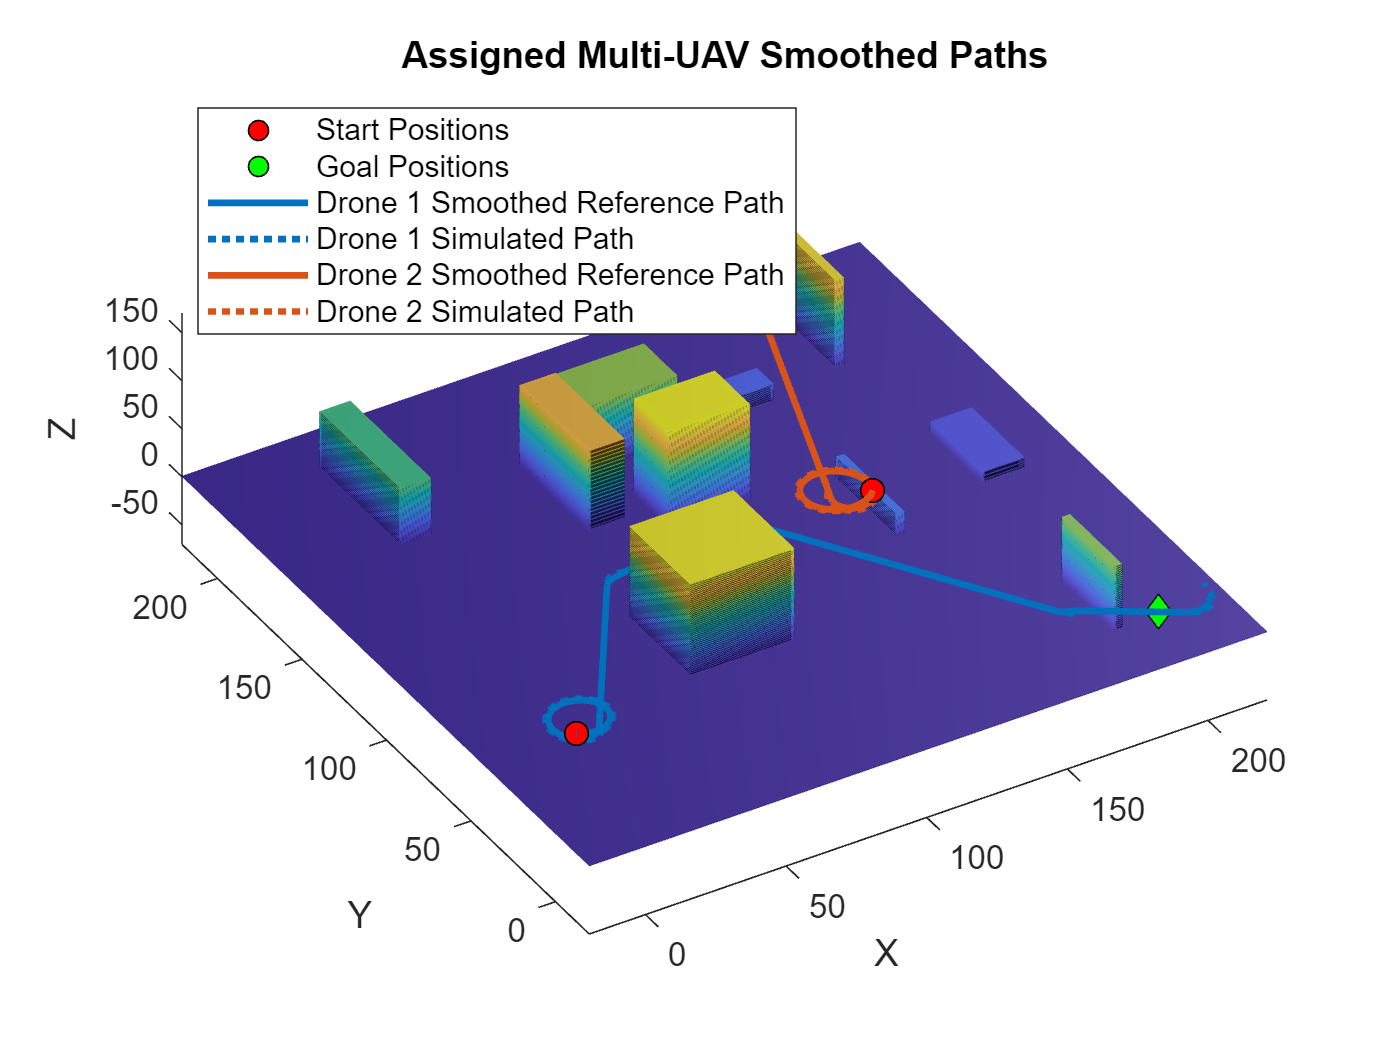

figure("Name", "Assigned Smoothed Drone Paths")
hMap = show(omap);
hold on

% Define a color map for different drones
colorMap = lines(length(swarm));

% Plot start positions
hStart = scatter3([], [], [], 50, 'r', 'filled', 'MarkerEdgeColor', 'k');

% Plot goal positions
hGoal = scatter3([], [], [], 50, 'g', 'filled', 'MarkerEdgeColor', 'k');

% Initialize arrays to store handles for drone paths
hReferencePaths = gobjects(1, length(swarm));
hSimulatedPaths = gobjects(1, length(swarm));

for i = 1:length(swarm)
    drone = swarm{i};
    
    % Plot start position
    scatter3(drone.StartPose(1), drone.StartPose(2), drone.StartPose(3), 50, 'r', 'filled', 'MarkerEdgeColor', 'k');
    
    % Get the assigned goal
    assignedGoal = drone.AssignedGoal;
    
    if ~isnan(assignedGoal) && assignedGoal > 0
        % Plot assigned goal position
        scatter3(drone.GoalPoses(assignedGoal, 1), ...
                 drone.GoalPoses(assignedGoal, 2), ...
                 drone.GoalPoses(assignedGoal, 3), ...
                 50, 'g', 'filled', 'MarkerEdgeColor', 'k', 'Marker', 'diamond');
        
        % Plot the smoothed path to the assigned goal if it exists
        if assignedGoal <= length(drone.GoalSolns) && ~isempty(drone.GoalSolns{assignedGoal})
            path = drone.GoalSolns{assignedGoal};
            
            % Smooth the path
            smoothWaypointsObj = exampleHelperUAVPathSmoothing(drone.Planner.StateSpace, drone.Planner.StateValidator, path);
            interpolatedSmoothWaypoints = copy(smoothWaypointsObj);
            interpolate(interpolatedSmoothWaypoints, 1000);
            
            % Plot the smoothed reference path
            hReferencePaths(i) = plot3(interpolatedSmoothWaypoints.States(:, 1), ...
                                       interpolatedSmoothWaypoints.States(:, 2), ...
                                       interpolatedSmoothWaypoints.States(:, 3), ...
                                       'LineWidth', 2, 'Color', colorMap(i, :));
            
            % Simulate the UAV trajectory based on the smoothed path
            waypoints = interpolatedSmoothWaypoints.States;
            timeToReachGoal = 1.05 * pathLength(smoothWaypointsObj) / drone.Planner.StateSpace.AirSpeed;
            [xENU, yENU, zENU] = exampleHelperSimulateUAV(waypoints, drone.Planner.StateSpace.AirSpeed, timeToReachGoal);
            
            % Plot the simulated path
            hSimulatedPaths(i) = plot3(xENU, yENU, zENU, 'LineWidth', 2, 'Color', colorMap(i, :), 'LineStyle', ':');
        end
    else
        fprintf('Drone %d has no assigned goal.\n', i);
    end
end

% Create legend
legend_entries = [hStart, hGoal];
legend_labels = {'Start Positions', 'Goal Positions'};

for i = 1:length(swarm)
    if isvalid(hReferencePaths(i))
        legend_entries(end+1) = hReferencePaths(i);
        legend_labels{end+1} = sprintf('Drone %d Smoothed Reference Path', i);
    end
    if isvalid(hSimulatedPaths(i))
        legend_entries(end+1) = hSimulatedPaths(i);
        legend_labels{end+1} = sprintf('Drone %d Simulated Path', i);
    end
end

legend(legend_entries, legend_labels, 'Location', 'best')

hold off
view([-31 63])
title('Assigned Multi-UAV Smoothed Paths')
xlabel('X')
ylabel('Y')
zlabel('Z')

#### Update Drone Start Poses

% Update start poses to the assigned goal poses after the mission
for i = 1:numDrones
    drone = swarm{i};  % Get the current drone
    
    % Check if the drone has an assigned goal (not NaN)
    if ~isnan(drone.AssignedGoal) && drone.AssignedGoal > 0
        % Get the position and heading of the assigned goal
        assignedGoalPose = drone.GoalPoses(drone.AssignedGoal, :);
        
        % Update the drone's start pose to its assigned goal pose (no heading retention)
        droneStartPoses(i, :) = assignedGoalPose;
    else
        % If no assigned goal, retain the original start pose
        % Optionally handle unassigned drones (e.g., mark them idle or assign a fallback)
        fprintf('Drone %d has no assigned goal.\n', i);
    end
end

droneStartPoses

droneStartPoses =   194.7056    0.4106   13.5149   -2.0745
  172.1787  212.3828   38.2082    1.2084


# Helper Functions

#### FindValidPose

function validPose = findValidPose(planner)
    while true
        pose = planner.StateSampler.sample()
        if planner.StateValidator.isStateValid(pose)
            validPose = pose;
            return;
        end
    end
end